# Transfer functions:

#  
$$K_k \;,K_v$$
 

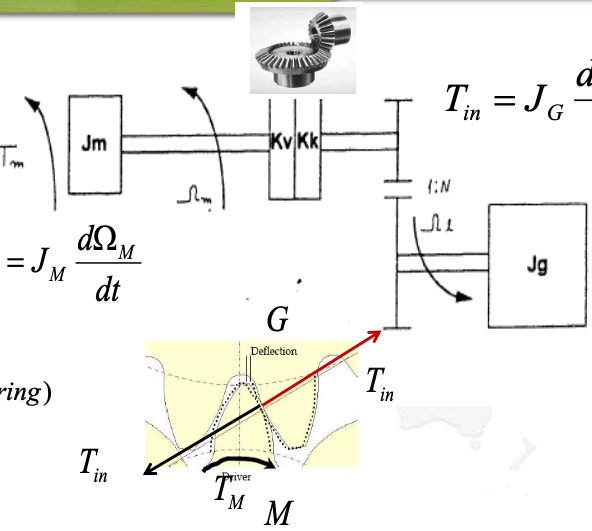


$$\begin{array}{l}
{\left(1\right)\;T}_M =I_c \cdot K_t \\
\left(2\right)\;T_M -T_{\textrm{in}} =J_M \frac{d\;\Omega_M \;}{\textrm{dt}}\\
\left(3\right)T_{\textrm{in}} =J_L \frac{d\Omega_L \;}{\textrm{dt}}\\
\left(4\right)T_{\textrm{in}} =K_k \int \left(\Omega_M -\Omega_L \right)\textrm{dt}+K_v \left(\Omega_M -\Omega_L \right)
\end{array}$$


eq 1: a torque current connection, with a unit constant

eq 2 : torque eqution for the Motor while

eq 3: torque eqution for the load while

eq 4: Terms getering damping and elastic chriceristics of the transsmision

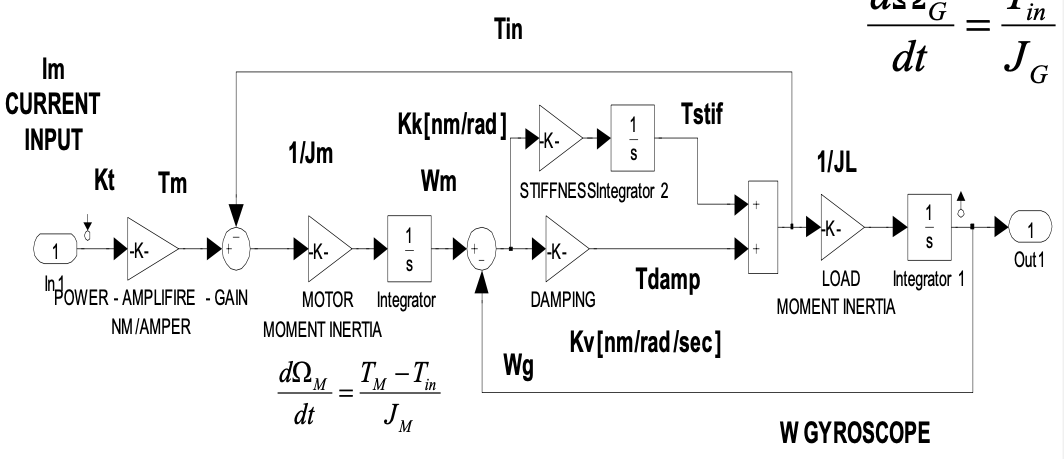


$$H_M \left(s\right)=\frac{\Omega {\;}_M \left(s\right)}{I_c }=\frac{K_t }{{\left(J_L +J_M \right)}^2 }\frac{1+\frac{K_v }{K_k }s+\frac{J_L }{K_k }s^2 }{1+\frac{K_v }{K_k }s+\frac{J_M J_L }{K_k \left(J_M +J_L \right)}s^2 }$$



$$H_L \left(s\right)=\frac{\Omega {\;}_L \left(s\right)}{I_c }=\frac{K_t }{{\left(J_L +J_M \right)}^2 }\frac{1+\frac{K_v }{K_k }s}{1+\frac{K_v }{K_k }s+\frac{J_M J_L }{K_k \left(J_M +J_L \right)}s^2 }$$


## `motor axis speed from engine current`

s = tf('s');
JMrtg = JMt+JLt/Nt^2+140;
JLrtg = JLt+JMt/Nt^2;

J_startg = (JMrtg*JLrtg)/(JMrtg+JLrtg);

Kktg=JLrtg/0.088^2;
Kvtg=0.01*Kktg;

fix_constg = 0.0060141;

pole_at_zero = fix_constg/(s);

complex_duble_zero = 1+Kvtg*s/Kktg+JLrtg*s^2/Kktg;

complex_duble_pole = 1+Kvtg*s/Kktg+J_startg*s^2/Kktg;

H_M = pole_at_zero*complex_duble_zero/complex_duble_pole;


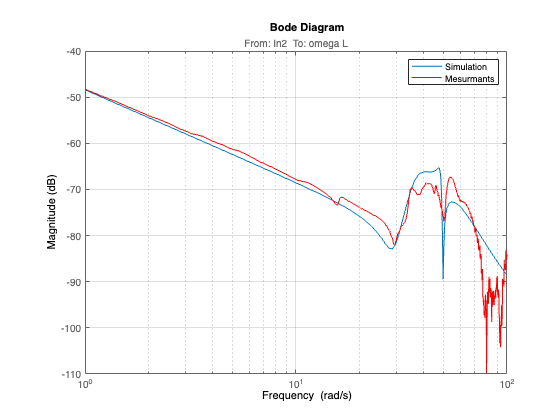

figure;
load('trav_gyro_sys.mat')
bodemag(trav_gyro_sys)
hold on
plot(trav_gyro_plant.o2i1x,trav_gyro_plant.g,Color='red')
legend('Simulation','Mesurmants')
xlim([1,100])
grid on;

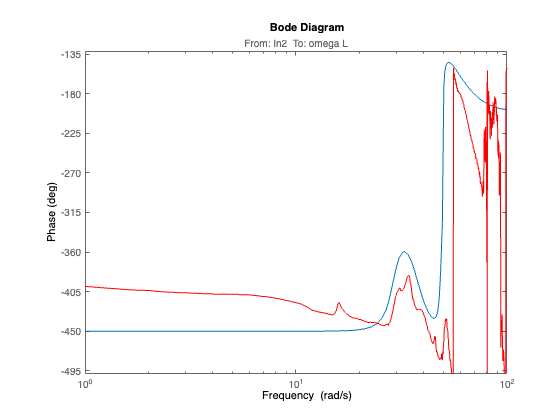

figure;
h = bodeplot(trav_gyro_sys);
setoptions(h,'MagVisible','off');
hold on
plot(trav_gyro_plant.o2i1x,trav_gyro_plant.p-330,Color='red')
xlim([1,100])

%ylim([min(trav_gyro_plant.p),max(trav_gyro_plant.p)])